clear all;
% Parâmetros de Configuração
zeta = 0.2;
w_n = 1;

% Cria a FT de segunda ordem
s = tf('s');
G = w_n^2 / (s^2 + 2*zeta*w_n*s + w_n^2)

G =
 
         1
  ---------------
  s^2 + 0.4 s + 1
 
Continuous-time transfer function.



% Calcula os polos e a envoltoria
sigma_d = real(pole(G));
sigma_d = abs(sigma_d(1))

sigma_d = 0.2000

w_d = imag(pole(G));
w_d = abs(w_d(1))

w_d = 0.9798


G_env = 1/(s+sigma_d)/sqrt(1-zeta^2)

G_env =
 
         1
  ----------------
  0.9798 s + 0.196
 
Continuous-time transfer function.



% Simula as respostas ao degrau

[y, t] = step(G);
[y_env, t] = impulse(G_env, t);

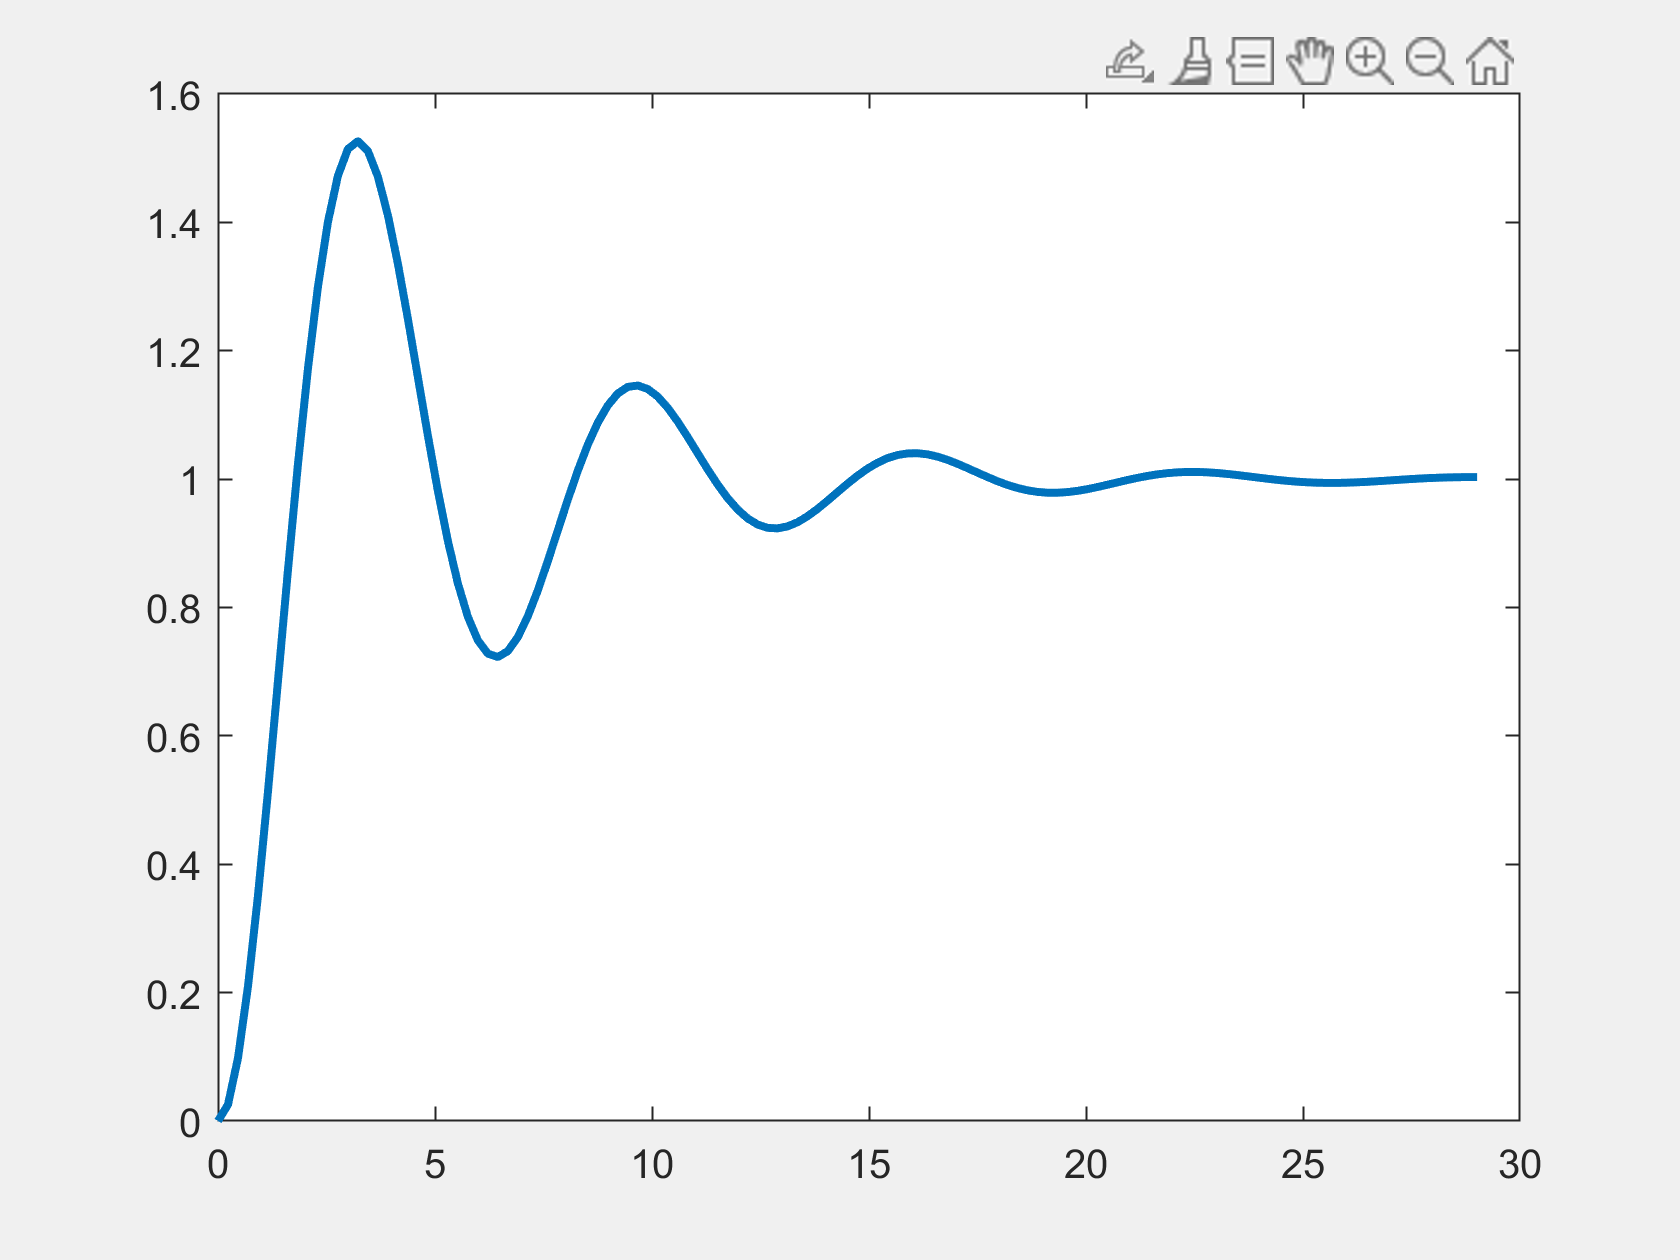

% Plota a resposta do Sistema Subamortecido
cmap = colororder;
figure; set(gcf,'Visible','on'); % plot also on window
plot(t, y, "Color", cmap(1,:), "LineWidth", 2);

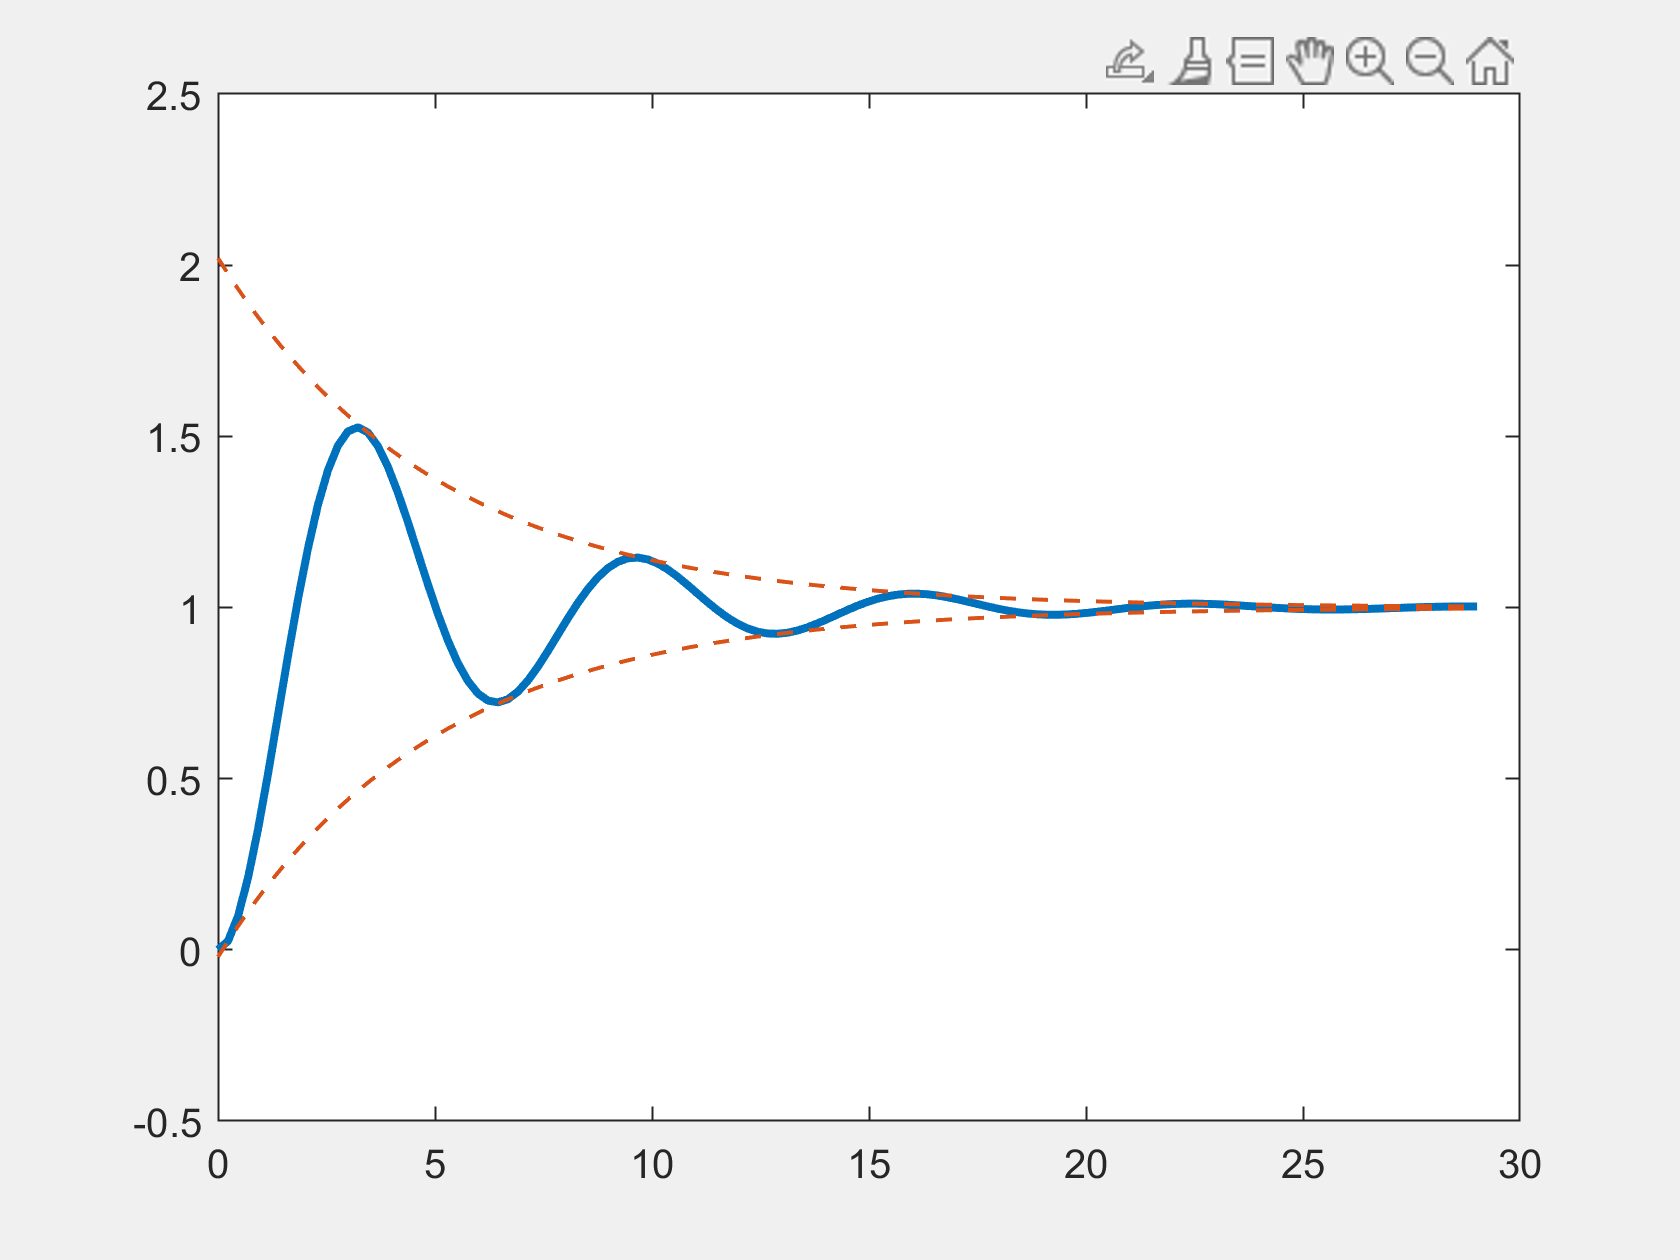

% Plota a resposta das envoltorias
hold on;
plot(t, 1-y_env, "Color", cmap(2,:), "LineWidth", 1, "LineStyle","--");
plot(t, 1+y_env, "Color", cmap(2,:), "LineWidth", 1, "LineStyle","--");